Name: Krish Singh

Roll no: Bl.ai.u4aid25072

Lab Excercise 4

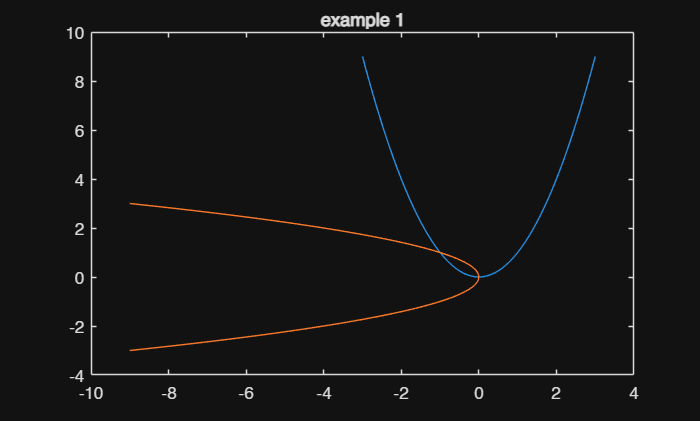

% Matrix transformation practice codes
%example 1
clf
t=-3:0.1:3;
x=[t;t.^2];
plot(t,t.^2)
hold on
A=[0,-1;1,0]; %rotation matrix for 90 degrees
y=A*x; %Transformation
plot(y(1,:),y(2,:))
hold off
title("example 1")

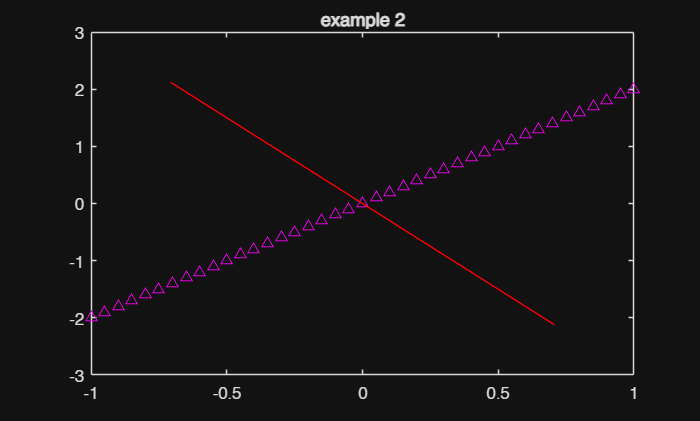

%example 2
clf
t=-1:0.05:1;
x=[t;2*t];
plot(t,2*t,'^m')
hold on
A=[1/sqrt(2),-1/sqrt(2);1/sqrt(2),1/sqrt(2)];
% the above code is based on rotation of matrix for angle 45 degrees
y=A*x; %transformation
plot(y(1,:),y(2,:),'r')
hold off
title("example 2")

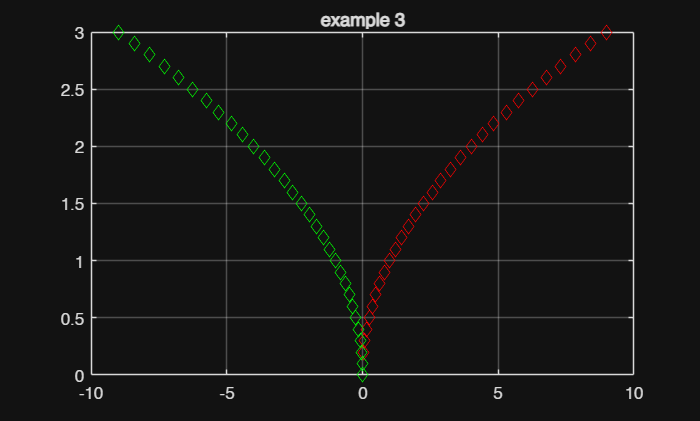

%Example 3
clf
t=0:0.1:3;
x=[t.^2;t];
plot(t.^2,t,'dr')
hold on
A=[-1,0;0,1];
y=A*x;
plot(y(1,:),y(2,:),'dg')
grid on
hold off
title("example 3")

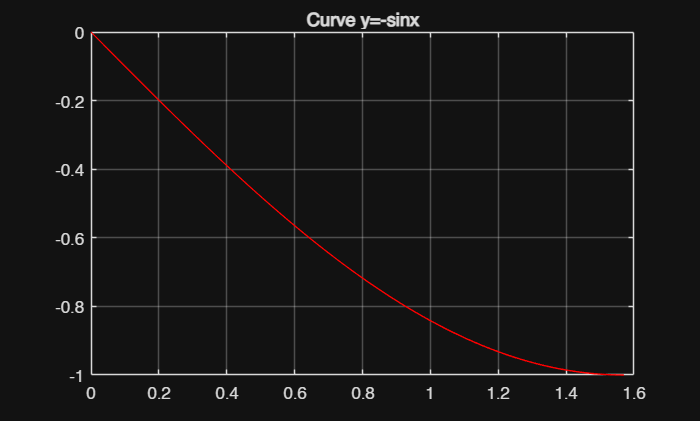

%Qno 1
clf
t=0:0.001:pi/2;
y=-sin(t);
x=[t;-sin(t)];
plot(x(1,:),x(2,:),'r');
grid on
title("Curve y=-sinx")

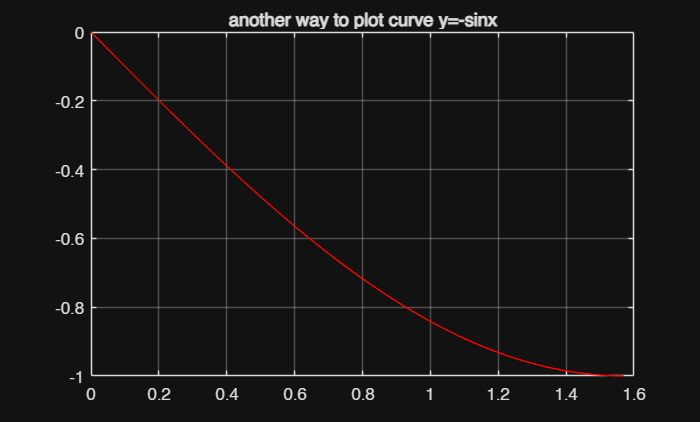

%another way to print the same
plot(t,y,'r')
grid on
title("another way to plot curve y=-sinx")

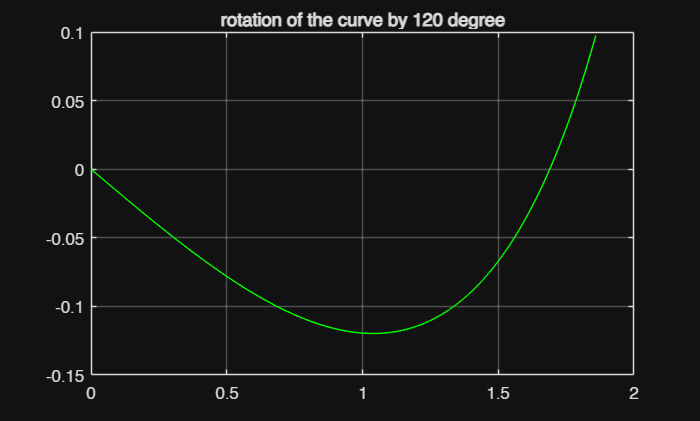


%Qno 1 a
A=[cos(120),-sin(120);sin(120),cos(120)];
y=A*x;
plot(y(1,:),y(2,:),'green')
grid on
title("rotation of the curve by 120 degree")

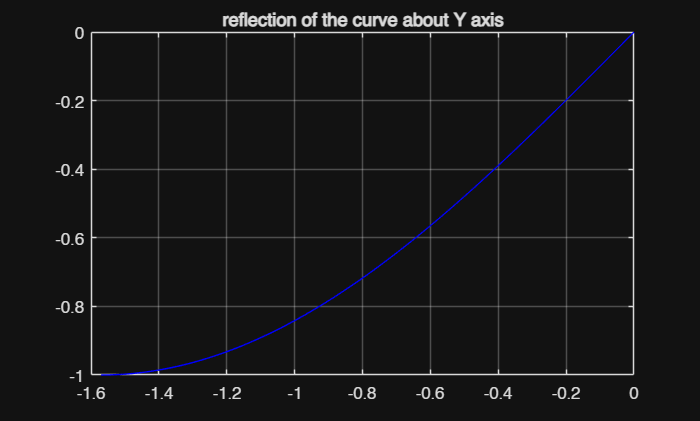

%qno 1 b
A=[-1,0;0,1];
y=A*x;
plot(y(1,:),y(2,:),'blue')
grid on
title("reflection of the curve about Y axis")

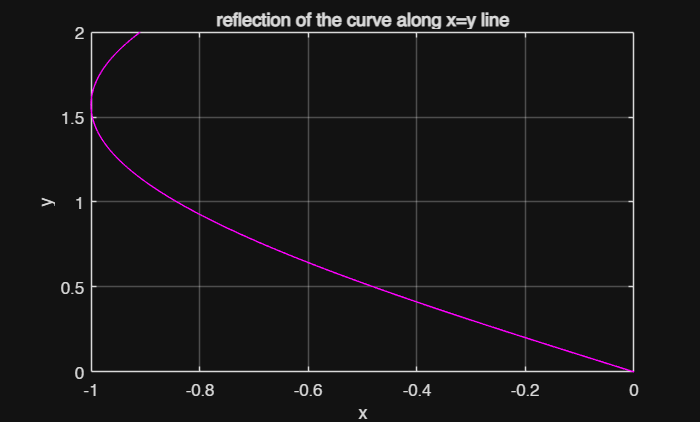

%qno 1 c
A=[0,1;1,0];
x=[t;-sin(t)]; 
y=A*x;
plot(y(1,:),y(2,:),'magenta')
grid on
title("reflection of the curve along x=y line")
xlabel("x")
ylabel("y")

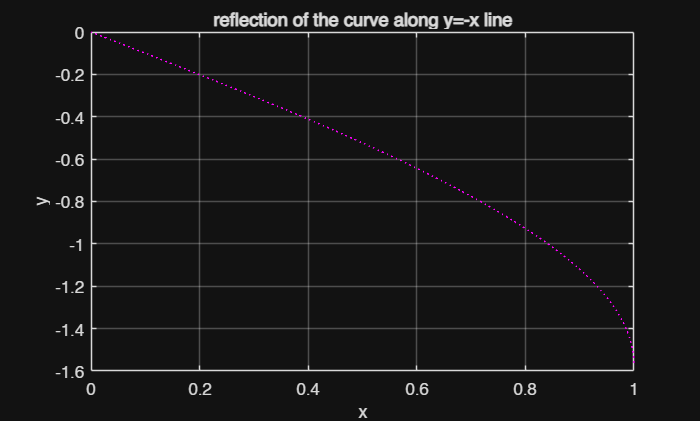

%qno 1 d
A=[0,-1;-1,0];
y=A*x;
plot(y(1,:),y(2,:),'magenta','LineStyle',':')
grid on
xlabel("x")
ylabel("y")
title("reflection of the curve along y=-x line")

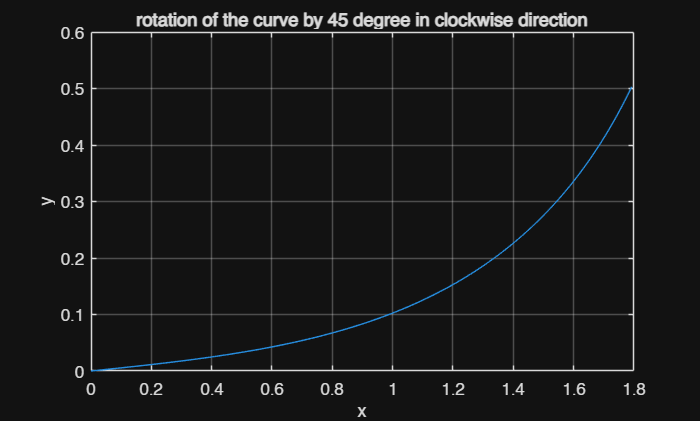

%qno 1 e
A=[cos(360-45),-sin(360-45);sin(360-45),cos(360-45)];
y=A*x;
plot(y(1,:),y(2,:))
grid on
xlabel("x")
ylabel("y")
title("rotation of the curve by 45 degree in clockwise direction")

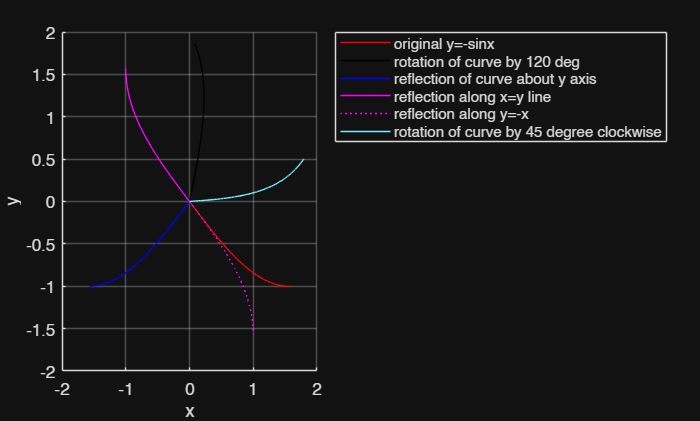

%qno 1 all in one plot 
%Qno 1
clf
t=0:0.001:pi/2;
y=-sin(t);
x=[t;y];
%Qno 1 a
A1=[cosd(120),-sind(120);sind(120),cosd(120)];
y1=A1*x;
%qno 1 b
A2=[-1,0;0,1];
y2=A2*x;
%qno 1 c
A3=[0,1;1,0];
y3=A3*x;
%qno 1 d
A4=[0,-1;-1,0];
y4=A4*x;
%qno 1 e
A5=[cos(360-45),-sin(360-45);sin(360-45),cos(360-45)];
y5=A5*x;
%plot
hold on
plot(x(1,:),x(2,:),'red')
plot(y1(1,:),y1(2,:),'-k')
plot(y2(1,:),y2(2,:),'blue')
plot(y3(1,:),y3(2,:),'magenta')
plot(y4(1,:),y4(2,:),'magenta','LineStyle',':')
plot(y5(1,:),y5(2,:))
hold off
xlabel("x")
ylabel("y")
grid on
legend('original y=-sinx','rotation of curve by 120 deg', ...
    'reflection of curve about y axis','reflection along x=y line', ...
    'reflection along y=-x','rotation of curve by 45 degree clockwise','Location','bestoutside')

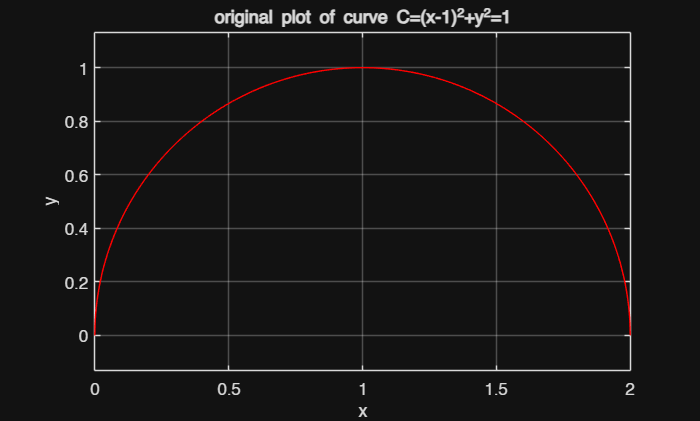

%qno 2 a
clf
t=0:0.001:2;
y=sqrt(1-((t-1).^2));
C=[t;y];
% or 
plot(C(1,:),C(2,:),'r');
grid on
axis("equal")
xlabel("x")
ylabel("y")
title('original plot of curve C=(x-1)^2+y^2=1')

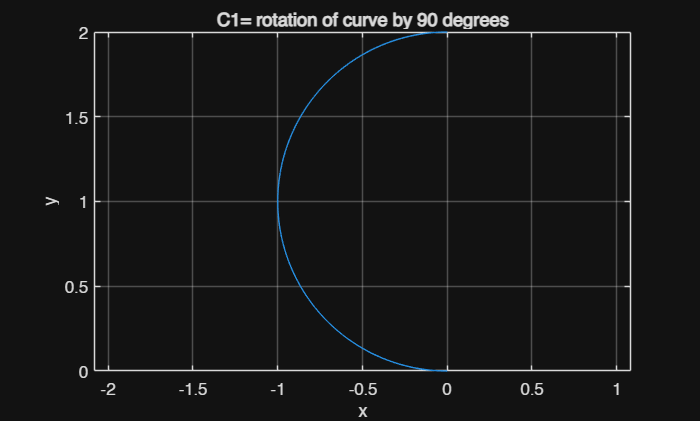

%qno 2b
clf
A=[cosd(90),-sind(90);sind(90),cosd(90)];
C1=A*C;
plot(C1(1,:),C1(2,:));
grid on
axis("equal")
xlabel("x")
ylabel("y")
title('C1= rotation of curve by 90 degrees')

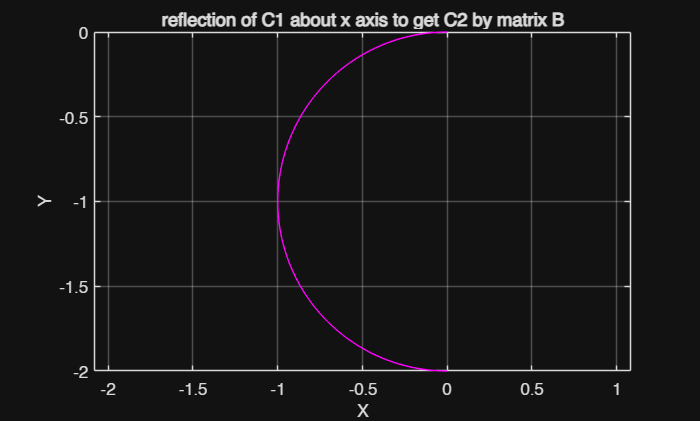

%qno 2c
B=[1,0;0,-1];
C2=B*C1;
plot(C2(1,:),C2(2,:),'magenta');
grid on
axis("equal")
xlabel("X")
ylabel("Y")
title("reflection of C1 about x axis to get C2 by matrix B")

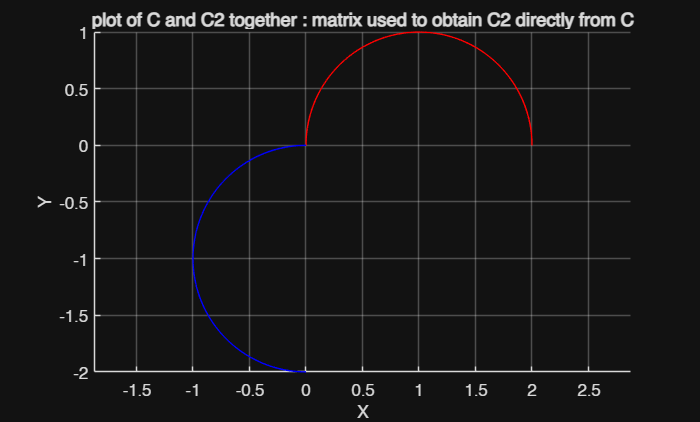

%qno 2d
clf
A2=B*A;
C3=A2*C;
hold on
plot(C(1,:),C(2,:),'r');
plot(C3(1,:),C3(2,:),'b')
hold off
axis("equal")
xlabel("X")
ylabel("Y")
grid on
title("plot of C and C2 together : matrix used to obtain C2 directly from C")

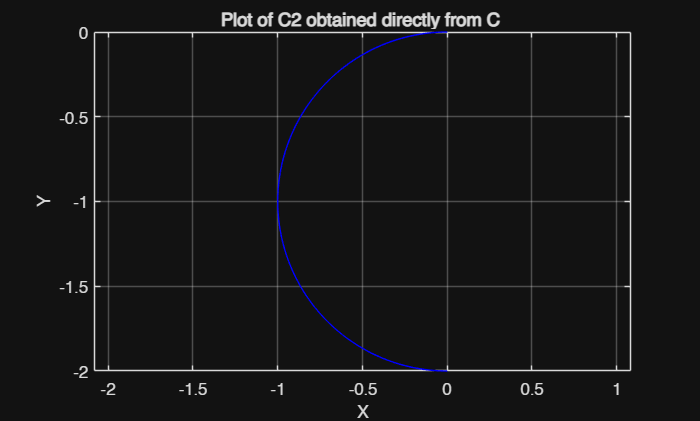

plot(C3(1,:),C3(2,:),'b')
axis("equal")
xlabel("X")
ylabel("Y")
grid on
title("Plot of C2 obtained directly from C ")

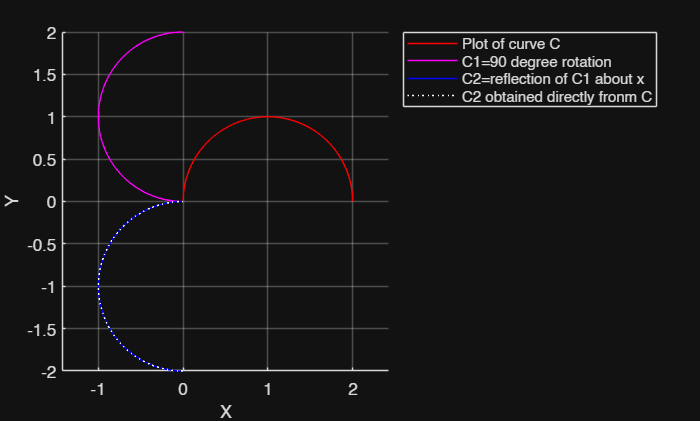

%qno 2 all in one plot
clf
t=0:0.001:2;
y=sqrt(1-(t-1).^2);
C=[t;y];
A=[cosd(90),-sind(90);sind(90),cosd(90)];
C1=A*C;
B=[1,0;0,-1];
C2=B*C1;
C3=B*A;
Fin=C3*C;
hold on
plot(C(1,:),C(2,:),'r');
plot(C1(1,:),C1(2,:),'magenta');
plot(C2(1,:),C2(2,:),'b');
plot(Fin(1,:),Fin(2,:),'white','LineStyle',':')
legend('Plot of curve C','C1=90 degree rotation','C2=reflection of C1 about x','C2 obtained directly fronm C','location','bestoutside')
axis("equal")
xlabel("X")
ylabel("Y")
grid on

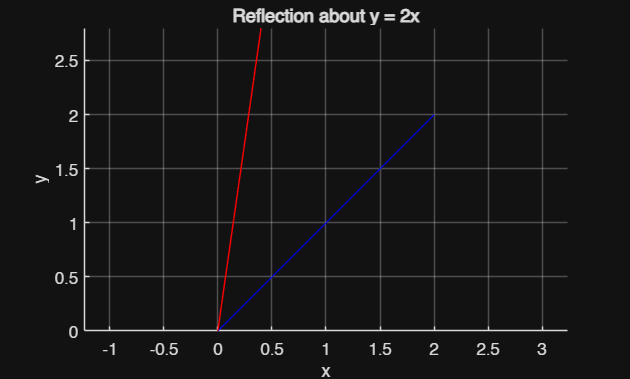

%qno 3
clf
x=0:0.001:2;
y=x;
A=[x;y]; %sample vector
%qno 3a
m=2; %qno y=mx where m=2 for this equation
R=(1/(1+m^2))*[1-m^2,2*m;2*m,m^2-1]; %matrix for reflection about y=2x
P1=R*A;
hold on
plot(A(1,:),A(2,:),'b'); %original vector
plot(P1(1,:),P1(2,:),'r'); % reflected vector
hold off
xlabel("x")
ylabel("y")
title('Reflection about y = 2x');
grid on
axis("equal")

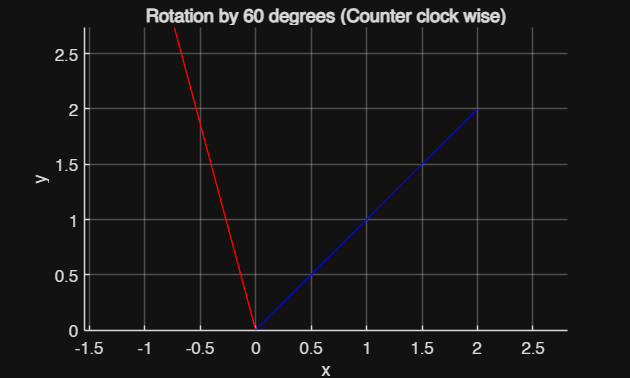

clf
%qno 3b
T=[cosd(60),-sind(60); sind(60),cosd(60)]; %matrix for rotation by 60 degree
P2=T*A;
hold on
plot(A(1,:),A(2,:),'b'); %original vector
plot(P2(1,:),P2(2,:),'r'); % rotation by 60 degree
hold off
xlabel("x")
ylabel("y")
grid on
title('Rotation by 60 degrees (Counter clock wise)');
axis("equal")

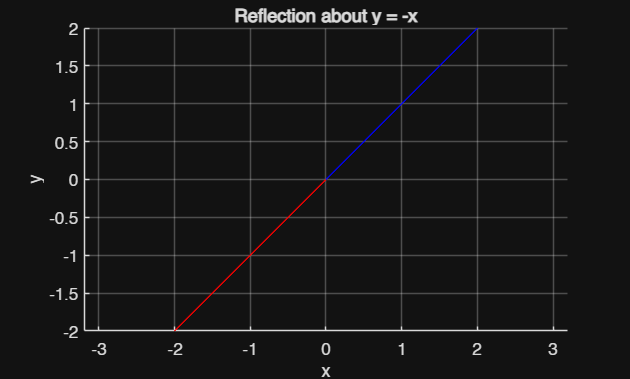

clf
%qno 3c
Y=[0,-1;-1,0]; % matrix for reflection about y=-x
P3=Y*A;
hold on
plot(A(1,:),A(2,:),'b'); %original vector
plot(P3(1,:),P3(2,:),'r'); % REFLECTION ABOUT Y=-X
hold off
xlabel("x")
ylabel("y")
grid on
title('Reflection about y = -x');
axis("equal")

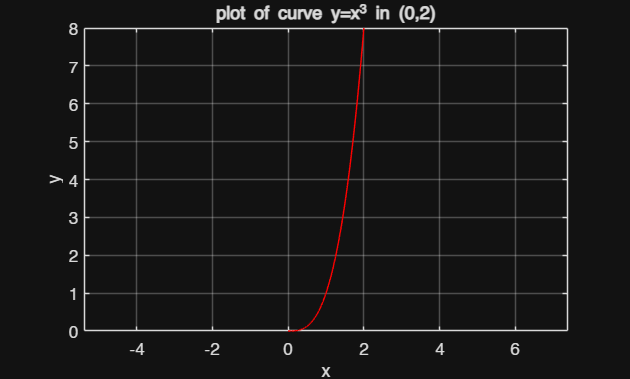

%qno 3 last 
x=0:0.001:2;
y=x.^3;
plot(x,y,'r')
grid on;
xlabel("x")
ylabel("y")
title("plot of curve y=x^3 in (0,2)")
axis("equal")

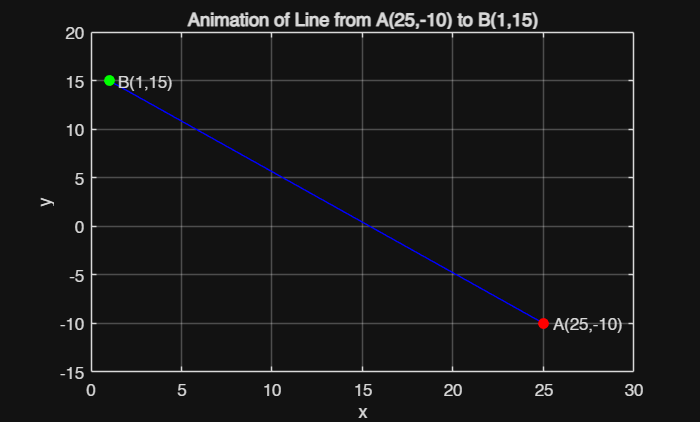

%qno 4 
close all;
figure(1);
clf
A=[25,-10];
B=[1,15];
x=linspace(A(1),B(1),100);
y=linspace(A(2),B(2),100);
for i=1:length(x)
    cla
    plot([A(1) x(i)],[A(2) y(i)],'b')
    drawnow
    pause(0.02)
    plot(A(1), A(2), 'ro', 'MarkerFaceColor', 'r') 
    plot(B(1), B(2), 'go', 'MarkerFaceColor', 'g')
    text(A(1)+0.5, A(2), 'A(25,-10)');
    text(B(1)+0.5, B(2), 'B(1,15)');
    grid on
    hold on
    xlabel ("x")
    ylabel("y")
    title('Animation of Line from A(25,-10) to B(1,15)')
    axis([0 30 -15 20])
end

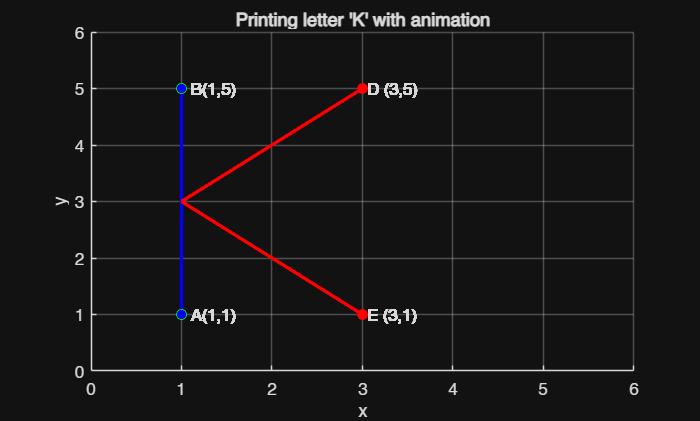

%qno 5
clc; clear; close all;
xlim([0 6]); ylim([0 6]);
xlabel('x'); ylabel('y');
title("Printing letter 'K' with animation");
hold on; grid on;
A = [1 1];
B = [1 5];
C = [1 3];
D = [3 5];
E = [3 1];
% vertical line
for y = linspace(A(2), B(2), 50)
    plot([A(1) A(1)], [A(2) y], 'b', 'LineWidth', 2);
    plot(A(1),A(2),'go','MarkerFaceColor','blue')
    plot(B(1),B(2),'go','MarkerFaceColor','blue')
    text(A(1)+0.05,A(2),' A(1,1)')
    text(B(1)+0.05,B(2),' B(1,5)')
    pause(0.01);
end
%upper diagonal
for t = linspace(0, 1, 50)
    x = C(1) + t*(D(1)-C(1));
    y = C(2) + t*(D(2)-C(2));
    plot([C(1) x], [C(2) y], 'r', 'LineWidth', 2);
    plot(D(1),D(2),'ro','MarkerFaceColor','r');
    text(D(1)+0.05,D(2), 'D (3,5)')
    pause(0.01);
end
%lower diagonal
for t = linspace(0, 1, 50)
    x = C(1) + t*(E(1)-C(1));
    y = C(2) + t*(E(2)-C(2));
    plot([C(1) x], [C(2) y], 'r', 'LineWidth', 2);
    pause(0.01);
    plot(E(1),E(2),'ro','MarkerFaceColor','r');
    text(E(1)+0.05,E(2),'E (3,1)');
end